# P4. Seguimiento de Trayectoria

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 19 Octubre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. Hasta ahora hemos diseñado el modelo de nuestro vehículo (planta del sistema) y el control longitudinal (ACC > Fx). En esta práctica implementaremos un controlador lateral sencillo basado en **Pure Pursuit** **> ángulo de giro de la dirección**. Será la primera vez que nuestro vehículo controle ambas dinámicas a la vez. 

💡 **Recordatorio**: *¿Qué es el Pure Pursuit?*

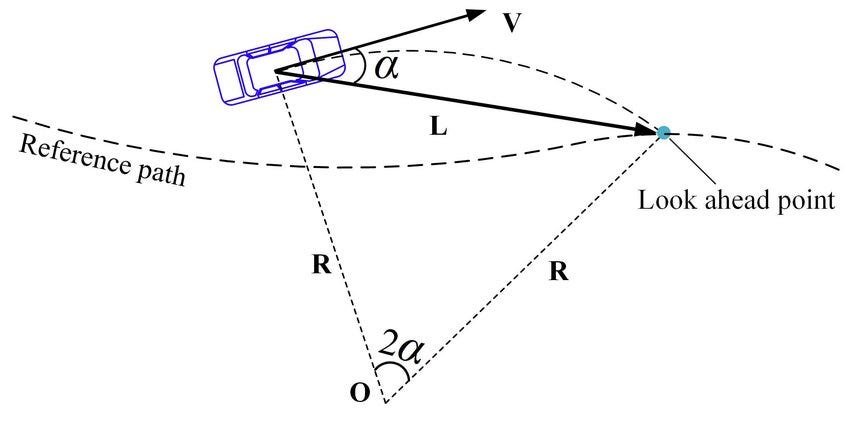

*Es un algoritmo geometrico simple de seguimiento de trayectorias utilizado en robótica y conducción autónoma. *

- *El algoritmo selecciona un punto objetivo (look-ahead point) sobre la ruta deseada a una distancia de anticipación (look-ahead distance) deseada *$L_d$* por delante del coche.*

- *Se calcula y traza el arco de circumferencia (*$\alpha$*) que, partiendo del coche con su rumbo actual, pasa por ese punto.*

- *El giro de volante necesario para conseguir ese arco es la salida del controlador.*

- *En cada ciclo de control, la posición del vehículo se actualiza y el punto objetivo avanza a lo largo de la trayectoria (el vehículo "persigue" la trayectoria).*

Referencia: Coulter, R. C. (1992). *Implementation of the pure pursuit path tracking algorithm* (No. CMURITR9201).

💡 En el caso de la Formula Student Driverless, la trayectoria de referencia vendrá definida por los conos del cicuito Autocross. 

El controlador lateral tendrá la forma:

% [Fx, mem] = controlLateral(est, path, p, mem)

- `est`  = el estado estimado del vehículo (posición, rumbo, velocidad...)

- path = la trayectoria de referencia: lista de puntos [x y] (línea central) 

- ref= las referencias de lo que buscamos; en este caso la velocidad de crucero deseada (`ref.v_set`) y la información del coche líder (`ref.lead_X`, `ref.lead_vx`)

- p = párametros (masas, resistencias, límites, ganancias, dt, etc.)

- mem = la memoría del controlador; estado interno que sobrevive de un paso al siguiente (integradores, comandos previos, etc).

Al terminar esta práctica deberás ser capaz de:

- Implementar el controlador lateral geométrico Pure Pursuit y hace que el vehículo siga una trayectoria de referencia.

- Integral el control lateral (dirección) con el control longitudinal (velocidad). 

- Medir el error de seguimiento (*cross-track error*) y ver dónde y por qué Pure Pursuit empieza a fallar.

#### Qué vas a implementar

A) El método Pure Pursuit como parte de `controlLateral. `

### Parametros del vehículo, controlador y de la calzada

p = struct(); % definición explicita (no es necesaria)

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta        = 0;      % inclinación de la calzada [rad]

% adherencia por eje
p.mu_t = 1.5; 
p.mu_d = 0.95*p.mu_t; 

% dinámica lateral del vehículo
p.ld = 0.765; % CG-eje delantero [m] % regla del FS drive es que la batalla tiene que ser superior a 1.525 m
p.lt = 0.765; % CG-eje trasero [m]
p.Iz = 130; % inercia en guiñada [kg·m^2]
p.Cad = 35000; % rigidez de deriva delantera [N/rad]
p.Cat = 50000; % rigidez de deriva trasera [N/rad]

% ley ACC
p.d0  = 6;       % distancia mínima parado [m]
p.h   = 1.5;     % tiempo de cabecera [s]                   
p.Kv  = 1.5;     % ganancia modo velocidad [1/s]            
p.Kg  = 0.4;     % ganancia modo distancia [1/s^2*m]    
p.Kd  = 1.0;     % ganancia sobre velocidad relativa [1/s]
p.jerk_max = 30; % límite de variación de aceleración (sobreaceleración, sacudidas) [m/s^3]

% control de velocidad sencillo
p.Kv_v = 800;
p.Ki_v = 200;




### Modelo del vehículo

Dado el **estado actual del vehículo, fuerza tractiva aplicada, y el ángulo de giro del volante** deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

% Integración de la dinámica longitudinal y lateral

function z_next = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); Y =z(2); psi = z(3);
    vx = z(4); vy = z(5); r = z(6);
    L = p.ld + p.lt;
    vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0 (angulos de deriva)
    
    % ángulos de deriva y fuerzas laterales
    alpha_d = delta - (vy + p.ld*r)/vx_c;
    alpha_t = - (vy - p.lt*r)/vx_c;
    Fyd = p.Cad*alpha_d; % modelo del neumático lineal 
    Fyt = p.Cat*alpha_t; % modelo del neumático lineal

    % Límite de adherencia (presupuesto mu·Fz por eje)
    Fzd = p.m*p.g*p.lt/L;  
    Fzt = p.m*p.g*p.ld/L;
    % Saturación eje delantero 
    Fyd = max(min(Fyd, p.mu_d*Fzd), -p.mu_d*Fzd); 
    % Saturación eje trasero  
    Fyt = max(min(Fyt, p.mu_t*Fzt), -p.mu_t*Fzt);
    % Agarre longitudinal
    Fx_max = p.mu_d*Fzd + p.mu_t*Fzt;
    Fx = max(min(Fx, Fx_max), - Fx_max);

    % Dinámica longitudinal 
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2;      % resitencia aerodinámica
    Rr  = p.fr*p.m*p.g*cos(p.theta);    % rodadura (opuesta al avance)
    Rg = p.m*p.g*sin(p.theta);          % gravedad (0 en E1)  
    
    % Ecuaciones del movimiento (chasis, CG)
    ax_l    = (Fx - Ra - sign(vx)*Rr- Rg) / p.m; % ecuación del movimiento de L1
    ax = ax_l + vy*r; % L1 + acoplamiento (componente centripeta, cambio en la dirección del vector velocidad por el giro)
    ay = (Fyd + Fyt)/p.m - vx*r;
    dr  = (p.ld*Fyd - p.lt*Fyt)/p.Iz;

    % Integración y cinemática global
    vx_next  = max(vx + ax*dt, 0);
    vy_next  = vy + ay*dt;
    r_next   = r  + dr*dt;
    X_next   = X + (vx*cos(psi) - vy*sin(psi))*dt;
    Y_next   = Y + (vx*sin(psi) + vy*cos(psi))*dt;
    psi_next = psi + r*dt;
    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next];
end

### Controlador de velocidad 

Vamos a definir un controlador de velocidad sencillo basado en una variante del diseñado en P1 (podría utilizarse el `controladorLongitudinal` de P3 pero no es necesario para esta práctica) y vamos a definir el `controlLateral` basado en Pure Pursuit ya en su forma final. 

### Geometría del circuito de pruebas

Vamos a simular la prueba de Autocross: una única vuelta a un circuito

% Pista de Autocross
ancho = 3.0; 
[centro, cono_izq, cono_der] = generarPista(ancho);
p.path = centro; 

function hist = simularE3(z0, p, centro, dt) %Autocross
    z = z0;  N = size(centro,1);
    mem_lat.idx = 1;  e_int = 0;
    Nmax = 60000;                         
    t=zeros(1,Nmax); X=zeros(1,Nmax); Y=zeros(1,Nmax); PSI=zeros(1,Nmax);
    VX=zeros(1,Nmax); ECT=zeros(1,Nmax);
    vuelta_ini = false;  k_fin = Nmax;
    for k = 1:Nmax
        est.X=z(1); est.Y=z(2); est.psi=z(3); est.vx=z(4); est.vy=z(5); est.r=z(6);
        % Control lateral (Pure Pursuit)
        [delta, mem_lat] = controlLateral(est, centro, p, mem_lat);
        % Control longitudinal (velocidad objetivo, PI simple)
        [Fx, e_int] = controlVelocidadSimple(p.v_set, z(4), e_int, dt, p);
        % Planta (bicicleta dinámica de L2)
        z = pasoDinamico(z, [Fx; delta], p, dt);
        % Registro + error lateral
        t(k)=(k-1)*dt; X(k)=z(1); Y(k)=z(2); PSI(k)=z(3); VX(k)=z(4);
        ECT(k) = errorLateral(z(1), z(2), centro);
        % ¿Vuelta completa? (se aleja del inicio y luego vuelve)
        d_ini = hypot(z(1)-centro(1,1), z(2)-centro(1,2));
        if ~vuelta_ini && d_ini > 10, vuelta_ini = true; end
        if vuelta_ini && d_ini < 2 && k > 100, k_fin = k; break; end
    end
    f=1:k_fin;
    hist.t=t(f); hist.X=X(f); hist.Y=Y(f); hist.psi=PSI(f); hist.vx=VX(f); hist.ect=ECT(f);
end

function e_ct = errorLateral(x, y, path)
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2;
    [~,i] = min(d2);  j = mod(i, size(path,1)) + 1;
    tang = atan2(path(j,2)-path(i,2), path(j,1)-path(i,1));
    dx = x-path(i,1); dy = y-path(i,2);
    e_ct = -sin(tang)*dx + cos(tang)*dy;
end

function [centro, cono_izq, cono_der] = generarPista(ancho)
    N = 240;  s = linspace(0, 2*pi, N+1)';  s(end) = [];
    a = 40; b = 26;
    xc = a*cos(s);
    yc = b*sin(s) + 6*sin(2*s);               
    centro = [xc, yc];
    dx = gradient(xc);  dy = gradient(yc);
    Ln = hypot(dx,dy);  nx = -dy./Ln;  ny = dx./Ln;
    cono_izq = [xc + (ancho/2)*nx, yc + (ancho/2)*ny];
    cono_der = [xc - (ancho/2)*nx, yc - (ancho/2)*ny];
end

### Simulación

dt = p.dt;
% Estado inicial: en el primer punto de la pista, orientado hacia el segundo
dir0 = atan2(centro(2,2)-centro(1,2), centro(2,1)-centro(1,1));

z0 = [centro(1,1); centro(1,2); dir0; p.v_set*0.5; 0; 0]; % estado inicial

hist = simularE3(z0, p, centro, dt); % Autocross

### Resultados 

Deberíamos observar como nuestro vehículo recorre la pista siguiendo la linea cetral. El error lateral debería mantenerse pequeño (decenas de cm) a esta velocidad. En las curvas más cerradas el vehículo recorta algo (dependiende de la distancia de anticipación). Este comportamiento es típico de Pure Pursuit. 

fprintf('L4 — error de seguimiento (cross-track):\n');
fprintf('   medio = %.2f m | máximo = %.2f m\n', mean(abs(hist.ect)), max(abs(hist.ect)));
fprintf('   vuelta completada en %.1f s (v_set = %.0f m/s)\n', hist.t(end), p.v_set);

% Gráficas
figure('Name','L4 · Pure Pursuit','Color','w');
subplot(1,2,1); hold on; axis equal; grid on;
  plot(cono_izq(:,1), cono_izq(:,2), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(cono_der(:,1), cono_der(:,2), 'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(centro(:,1), centro(:,2), 'k:','LineWidth',0.8);
  plot(hist.X, hist.Y, 'r-','LineWidth',1.4);
  legend('conos izq (azul)','conos der (amarillo)','línea central','trayectoria','Location','bestoutside');
  title('Pista de Autocross'); xlabel('X [m]'); ylabel('Y [m]');
subplot(1,2,2);
  plot(hist.t, hist.ect,'r','LineWidth',1.2); grid on;
  ylabel('error lateral [m]'); xlabel('t [s]'); title('Error de seguimiento (cross-track)');

Prueba a subir la velocidad. *¿Qué velocidad máxima puedes alcanzar manteniendo el error de seguimiento por debajo de 1m?* *¿Qué velocidad hace que el vehículo se salga del circuito?*